# Supervised Learning - Week 3 / Part 5

## Regularization to Reduce Ovefitting

It is important to be able to realize that overfitting or underfitting might be occurring in our training processes. Let's see what we can do if we are suspecting that our training is suffering from overfitting. Let's say we have a model and it has a high variance, in other words it is overfitting. Let's see the overfitting house prediction model as follows:

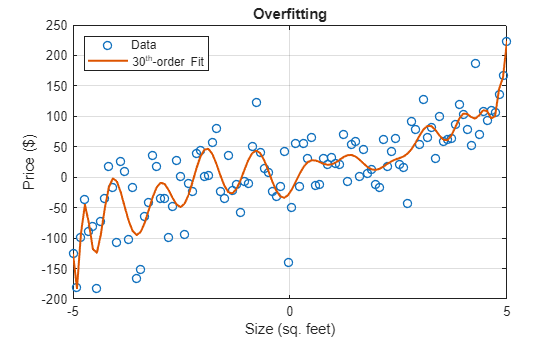

rng(11);
co = colororder;

% Synthetic house size vs. prices data
lim_house_size = [-5 5];
house_size = linspace(min(lim_house_size), max(lim_house_size), 110).';
house_price = house_size.^3 + house_size.^2 + 2*house_size + 3 + randn(size(house_size))*45;

% Load and plot overfitting 30-th degree polynomial model with the data
load("polyfit_30.mat")
x1_val = (house_size-mu(1))./mu(2);
xval_mtx = x1_val.^(30:-1:0);

figure;
plot(house_size, house_price, 'o', 'LineWidth', 1)
hold on
plot(house_size, sum(p.*xval_mtx,2), '-', 'LineWidth', 1.5)
xlabel('Size (sq. feet)')
ylabel('Price ($)')
grid on
hold off
legend('Data', '30^{th}-order Fit', 'Location', 'northwest')
title("Overfitting")

**One way to address this problem** is to collect more training data. If you are able to get more training samples then the learning algorithm learns to fit a function that is less wiggly. Thus, we can continue to fit a high order polynomial or some function with a lot of features and if we have enough training examples it will still do okay. As a summary, the number one tool we can use against overfitting is to get more training data. Getting more data isn't always an options since there may be only so many houses have been sold in this location and maybe there is no more information to be added. However, if the data was available this would work really well.

**Second option for addressing overfitting is to see if you can use fewer features.** In the previous week's application our input features included the size ($x$), size squared ($x^2$), cubed ($x^3$), fourth ($x^4$) so on and so forth, where those were a lot of polynomial features. To reduce the overfitting we can use reduced number of polynomial features. Let's look at the following example:

Let's assume that we have the following features of a house which we try to predict its price,

It turns out that if we have a lot of features like the above example, but don't have enough training data, then our learning algorithm might overfit our training set. Instead of using 100 features, we can select a subset of the most useful ones. For instance,

Using just a smallest subset of features, we may find that our model no longer overfits as badly. Choosing most appropriate set of features is also called **feature selection**. One way to select the features is to use our intuition, choosing what we think is the most relevant to predicting the price of a house. One disadvantage using only a subset of the features is that we are throwing away some of the information about the houses that could have been useful to capture underlying relationships using a model. 

- What happens if all 100 features are useful for predicting the price of a house?

- Maybe we don't want to throw away some of the features. 

- Then what is going to happen?

Later in this series we will also see an automatic way of choosing the set of most appropriate features to use for our prediction task. As a third alternative to reduce overfitting is called **regularization**. If you look at an overfitting model, such as the one above,

$f(x) = x^3 + x^2 + 2x + 3 +  n$,

 where $n$ is a random noise. We can see from this expression that the parameters are relatively large; $x^3$, $x^2$, $x$. More importantly, large parameters/coefficients correspond to very rapid oscillations as depicted below,

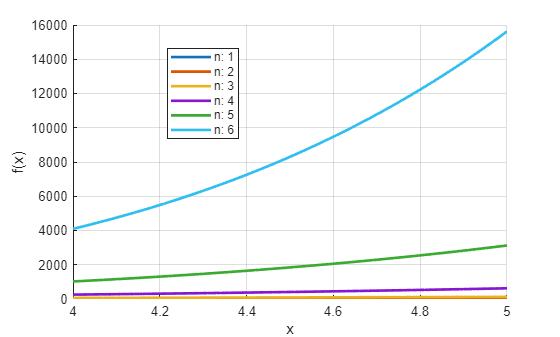

n_vec = 1:6;
y = 4:0.01:5;

figure
hold on
for i = 1:length(n_vec)
    n = n_vec(i);
    plot(y, y.^n, 'LineWidth', 2)
end
hold off
grid on
xlabel('x')
ylabel('f(x)')
legend(arrayfun(@(x) "n: "+x, n_vec), 'Location', 'best')

As can be seen from the above plot, 1 unit change in $x$ corresponds to approximately 11 500 unit change in $f(x) = x^6$. Hence, the contribution of $x^6$ term in a training algorithm will sway drastically with a minimal change in $x$.

- If we were able to eliminate some these very large valued features that would solve our overfitting issue. However, eliminating a higher order parameter corresponds to setting this parameter to 0. The problem with this approach is that setting a parameter to zero is a very harsh way of doing things. More importantly, we might benefit from the higher-order terms especially if the data we are trying to fit is very complex.

- It turns out that the regularization is a more gentle way to reduce the influence of the higher order (large) parameters rather than harshly setting them up to 0, which would discard them entirely.

- What regularization does it to encourage the learning algorithm to shrink the values of the parameters without demanding that the parameter must be set to 0. Even if we try to fit a higher order polynomial like$f(x) = 13x - 0.23x^2 + 0.000014x^3 - 0.0001x^4 + 10$, as long as we get the algorithm to use smaller parameter values (e.g. $w_1, w_2, \cdots, w_j$) for corresponding higher order (large) parameters, we end up with a curve which will be fitting data much better.

Let's visualize the main idea behind the regularization,

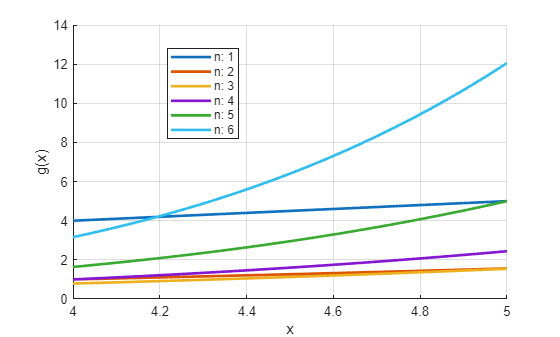

n_vec = 1:6;
y = 4:0.01:5;

figure
hold on
for i = 1:length(n_vec)
    n = n_vec(i);
    plot(y, (1/(n^4))*y.^n, 'LineWidth', 2)
end
hold off
grid on
xlabel('x')
ylabel('g(x)')
legend(arrayfun(@(x) "n: "+x, n_vec), 'Location', 'best')

As can be seen from the above example, we are penalizing the high order polynomials proportional with their order, which takes the original polynomial $f(x) = x^n$ and transforms into$g(x) = \frac{1}{n^4}x^n$ as can be seen from the $g(x)$, larger order polynomials are punished more, which makes lower and higher order polynomial's contribution in the comparable order. For instance, after the regularization 1 unit change in $x$ corresponds to approximately 8.9 unit change in $f(x) = r_6x^6$, where $r_6$ is the regularization term.

What regularization does is it let's you to keep all of your features, but it prevents the high-order features to have an overly large effect on the model, which can cause overfitting. By convention, the regularization is done by reducuing the sizes of the parameters ($w_j$, where $j \in \{ 1,2,\cdots, n \}$). It doesn't make a huge difference whether you also regularize the parameter $b$ or not. For simplicity, we won't regularize the bias term in our applications for simplicity.In practice, regularization of b should make very little difference.

### Recap: Addressing overfitting

There three ways to address overfitting issue,

- **Collect more data:** If doable this can help really help reduce overfitting. This solution might not be feasible in every problem/scenario. If it is feasible, this is the straightforward way to reduce overfitting since doesn't require any change in the model.

- **Select subset of featues:** This solution will be explained further in the following tutorials. The problem with this solution is that the whole features set might have some importance for model to generalize the underlying behaviour. Moreover, selection of the features brings an additional dimension to the problem since it would affect the model performance directly.

- **Reduce the size of parameters using "Regularization":** This is a very useful technique not only for linear and logistic regression applications but also neural networks specifically.

### Futher Insight: Overfitting

- A high-order polynomial model will have enough flexilibility to pass exactly through every training point, especially if there are very few of them (sparse data). When you fit such a complex curve to a small dataset, the model can end up wiggling to interpolate any noise or tiny fluctuations in the training labels rather than captureing the true underlying trend. In other words, it will have a very low training error but poor generaralization on new points - this is exactly what we mean by overfitting.

- What can be done to avoid overfitting? 

**1) Adding more data points:** As we add data, the model faces more constraints where it can no longer contort itself to fit small number of points (e.g. 20 points); now it needs to fit 100, 500, or 10 000 points. If those extra points actually reflect the same underlying pattern (plus noise), a model that was previously over-wiggly will be pulled towards the true trend. 

**2) Reducing number of features: **If you have many features but relatively few training examples, the model can memorize idiosyncratic patterns in the noise. For instance, for a linear model each feature adds another coefficient to fit; if you have $n$ features and $m$ observations with $m \approx n$ or $n > m$, there are infinitely many ways to drive th training error to zero since we end yo with fewer independent equations than unknowns,

$y^{(i)} = w_1x_1^{(i)} + w_2x_2^{(i)} + \cdots + w_nx_n^{(i)}$.

Similarly, the whole system (all the samples and features combined) can be represented as $\mathbf{y} = \mathbf{X}\mathbf{w}$, where we assume there is no bias term for simplicity. Note that the features matrix is $m \times n$ rectangular matrix, which indicates that the solution of this linear system is underdetermined. Consequently, an undetermined system can always be made to have zero training error in infinitely many distinct ways.

**3) Using regularization techniques:** The regularization means that we add a penalty term to the loss function, where the new term discourages any weight coefficient from growing extremely large. Note that large coefficients correspond to very rapid oscillations in the polynomial basis. With regularization we find a hyperparameter which ensures that our polynomial is complex enough to capture the true trend, yet not so wild that is chases noise. In other words, regularization effectively reduces the degrees of freedom if a high-degree basis, forcing the learned curve to stay in the **lower-variance regime**.

## Optional Lab: Overfitting

### Goals

In this lab, we will explore the situations where overfitting can occur and also get some insight about the possible the solution methods.

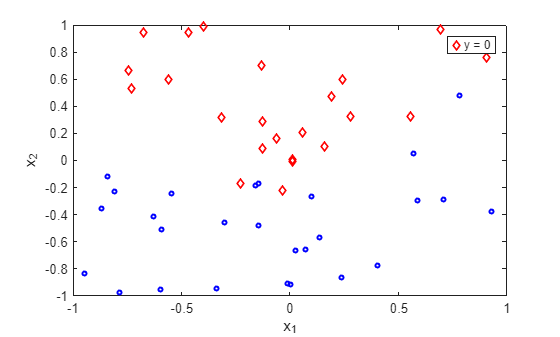

% Generate training features and labels. Please note that certain parameter
% values hardcoded to match Machine Learning course results
m = 50; % number of samples
n = 2; % number of classes
[X_train,y_train] = logisticRegressionData(m,n);

% Plot data
figure;
hBinaryScatter(X_train, y_train, {'o','d'},{'b','r'}, 3)
legend("y = 0")
xlabel("x_1")
ylabel("x_2")

### Appendix: Squared Uniform Distribution

Note that the generation of the training labels are calculated using the following expression:

which contains the following term $Y = X^2$, where $X ~ \sim U(0,1)$. Note that the range of the squared random variable will be same as the original distribution $Y: (0^2, 1^2)$.

#### CDF

We can calculate the new distribution's cumulative distribution function (CDF) by using the uniform distribution. For simplicity, we only consider the MATLAB's `rand` function which has the following probability distribution function (PDF), $f(x) = 1$. Thus, we can calculate the CDF of the square uniform distribution as follows:


$$F_Y(y) = P(Y \leq y) = P(X^2 \leq y) = P(X \leq \sqrt{y}) \\
= F_X(\sqrt{y}), \quad \text{for}~~ 0\leq y \leq 1$$


We know that the CDF of the uniform distribution can be calculated by,

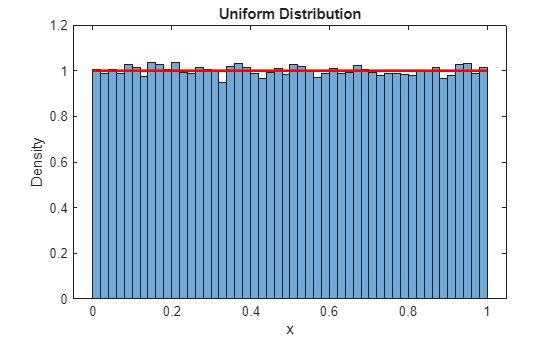

figure;
histogram(rand(1, 1e5),"Normalization","pdf")
hold on
x = 0:0.01:1;
plot(x, ones(1, length(x)),'r-', "LineWidth", 2)
hold off
xlabel("x")
ylabel("Density")
title("Uniform Distribution")

As can be above, $F_X(x) = P(X \leq x) = \int_0^x 1 dx =x$. Therefore, $F_Y(y) = F_X(\sqrt{y}) = \sqrt{y}$.

#### PDF

Since we know the CDF of the squared uniform distribution, we can calculate its PDF as follows:


$$f(y) = \frac{d}{dy}F_Y(y) = \frac{d}{dy} \sqrt{y} = \frac{1}{2\sqrt{y}}$$


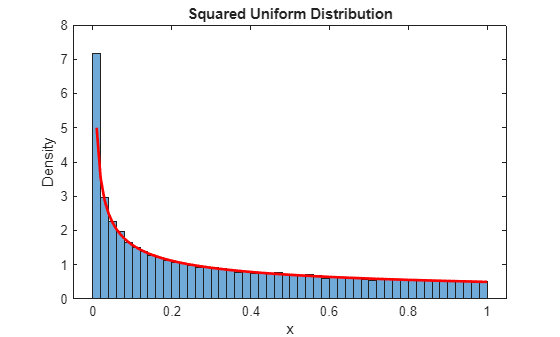

figure;
histogram(rand(1, 1e5).^2,"Normalization","pdf")
hold on
y = 0:0.01:1;
plot(y, ones(1, length(y))./(2.*sqrt(y)), 'r-', "LineWidth", 2)
hold off
xlabel("x")
ylabel("Density")
title("Squared Uniform Distribution")

Let's fit a linear and logistic regression curves to the given data with different order 

## Local Functions

function [X_train,y_train] = logisticRegressionData(m,n)
    rng(2)
    X_train = 2*(rand(m,n)-[0.5 0.5]); % uniform (-1, 1)
    % y_train = uniform (-0.5, 1.5) > 
    y_train = X_train(:,2)+0.5 > X_train(:,1).^2 + 0.5*rand(m,1);
end